# Telemonitoring Parkinson's Disease

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data.

dataTrain = readtable("./data/parkinsons.xlsx", Sheet="dataTrain");
dataTest = readtable("./data/parkinsons.xlsx", Sheet="dataTest");
whos dataTrain dataTest

  Name              Size             Bytes  Class    Attributes

  dataTest       1762x20            287165  table              
  dataTrain      4113x20            663325  table              



## Fit regression model

This data set contains biomedical voice measurements from a study of subjects with early-stage Parkinson's disease. The goal is to predict the clinician's Parkinson's disease symptom score on the UPDRS scale.

The table `data` contains several predictor variables and a response in an interior column named `"total_UPDRS"`. The data has been split into training and test sets: `dataTrain` and `dataTest`.

Fit model then predict response for test data.

mdl = fitrtree(dataTrain, "total_UPDRS");
yPred = predict(mdl, dataTest);

Compare predicted and actual responses.

***MSE is displayed in the following plot:***

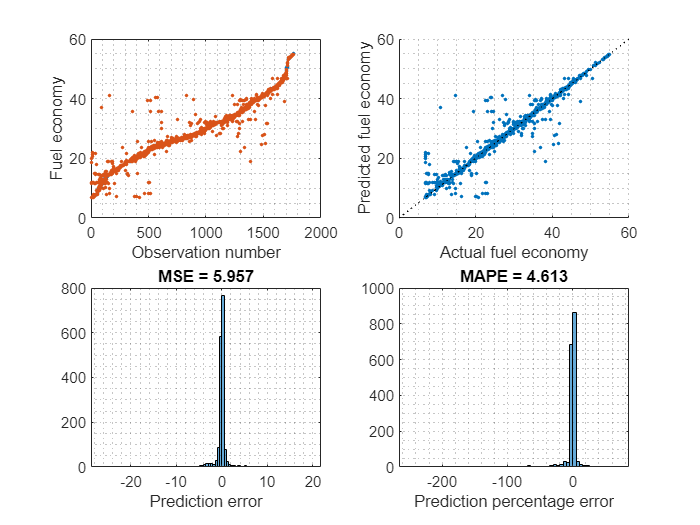

evaluateFit(dataTest.total_UPDRS, yPred, "")

function evaluateFit(y, ypred, name)
    figure
    % Plot against observation number
    subplot(2,2,1)
    plot(y,'.')
    grid minor
    hold on
    plot(ypred,'.')
    hold off
    title(name)
    xlabel('Observation number')
    ylabel('Fuel economy')
    
    % Plot predicted and actual against each other
    subplot(2,2,2)
    scatter(y,ypred,'.')
    grid minor
    % Add 45-degree line
    xl = xlim;
    hold on
    plot(xl,xl,'k:')
    hold off
    title(name)
    xlabel('Actual fuel economy')
    ylabel('Predicted fuel economy')
    
    % Distribution of errors
    subplot(2,2,3)
    err = y-ypred;
    MSE = mean(err.^2,'omitnan');
    histogram(err)
    grid minor    
    title(['MSE = ',num2str(MSE,4)])
    xlabel('Prediction error')
    
    % Distribution of percentage errors
    subplot(2,2,4)
    err = 100*err./y;
    MAPE = mean(abs(err),'omitnan');
    histogram(err)
    grid minor
    title(['MAPE = ',num2str(MAPE,4)])
    xlabel('Prediction percentage error')
end
